# Newton Method for Finding Maximum or Minimum

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2018-12-10

### Taylor expansion

reference: [http://mathworld.wolfram.com/TaylorSeries.html](http://mathworld.wolfram.com/TaylorSeries.html) 

A Taylor series is a series expansion of a function about a point. A one-dimensional Taylor series is an expansion of a real function about a point x


$$f\left(x\right)=f\left(a\right)+f^{\prime } \left(a\right)\left(x-a\right)+\frac{1}{2}{f^{\prime } }^{\prime } \left(a\right){\left(x-a\right)}^2 +\cdots$$


### Newton method

reference: [https://en.wikipedia.org/wiki/Newton%27s_method_in_optimization](https://en.wikipedia.org/wiki/Newton%27s_method_in_optimization)

Newton's method attempts to find the roots of $f'$by constructing a sequence $x_n$from an initial guess $x_0$that converges towards some value $x^*$satifying $f'(x^*)=0$. This $x^*$is a stationary point (differentiable) of $f$. The second-order taylor exapnasion $f_T(x)$of a function $f$around $x_n$ is


$$f_T(x)=f_T(x_n+\Delta x) \approx f(x_n)+f'(x_n)\Delta x+\frac 1 2 f''(x_n) \Delta x^2
$$


Ideally, we watn to pick a $\Delta x$ such that $x_n + \Delta x$ is a stationary point of $f$. Using this Taylor expansion as an approximation, we can at least solve for the $\Delta x$corresponding to the root of the expansion's derivative:


$$0 = \frac{\rm d}{\rm d\Delta x} \left(f(x_n)+f'(x_n)\Delta x+\frac 1 2 f''(x_n) \Delta x^2\right) = f'(x_n)+f'' (x_n) \Delta x
$$



$$\Delta x = -\frac{f'(x_n)}{f''(x_n)}$$


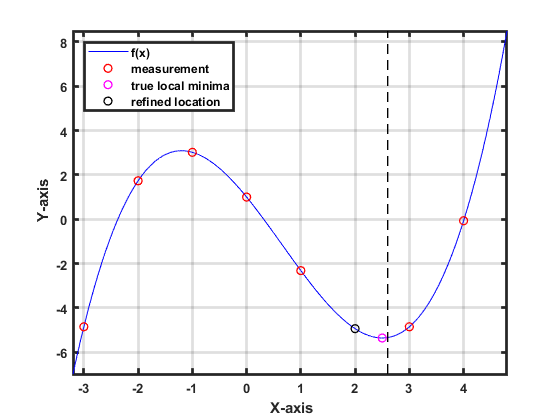

% equation: 1/3x^3 - 0.65x^2 - 3x + 1
% derivative: x^2 - 1.3 x - 3 = (x-2.5)(x+1.2)

% symbolic equation
syms a
eq = 1/3*a^3 - 0.65*a^2 - 3*a + 1 ==0;
true_local_max_min_syms = solve(diff(eq, a), a, 'MaxDegree', 2)';
t_loc_max_min_x = vpa(true_local_max_min_syms);

% numerical equation

% polynomial function
p = [1/3 -0.65 -3 1];
x = -3.2:0.001:4.8;
y = polyval(p, x);
yp = diff(y)/0.001;
xp = x+0.005; xp(end)=[];
ypp = diff(yp)/0.001;
xpp = xp+0.005; xpp(end)=[];

% measurement
idx_sample = ismembertol(x,-3:4, 10^-6);
data_x = x(idx_sample);
data_y = y(idx_sample);

t_loc_max_min_y = zeros(numel(t_loc_max_min_x), 1);
for ii=1:numel(true_local_max_min)
    [~, idx] = min(abs(x-t_loc_max_min_x(ii)));
    t_loc_max_min_y(ii) = y(idx);
end

local_min_x = data_x(islocalmin(data_y));
local_min_y = data_y(islocalmin(data_y));
delta_x = -interp1(xp, yp, local_min_x)/interp1(xpp, ypp, local_min_x);
local_min_x_refine = local_min_x + delta_x;

figure(1)
plot(x,y,'b'); hold on; 
plot(data_x, data_y, 'or', 'linewidth', 1); 
plot(t_loc_max_min_x(2), t_loc_max_min_y(2), 'om', 'linewidth', 1); 
plot(local_min_x, local_min_y, 'ok', 'linewidth', 1); 
line([local_min_x_refine local_min_x_refine], [min(y) max(y)], 'linestyle', '--', 'color', 'k', 'linewidth', 1); hold off;
legend({'f(x)', 'measurement', 'true local minima', 'refined location'}, 'location', 'northwest')
axis tight; grid on;
xlabel('\bf X-axis'); 
ylabel('\bf Y-axis');
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold')

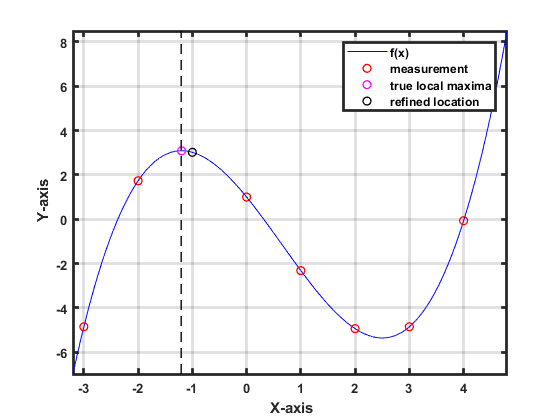



local_max_x = data_x(islocalmax(data_y));
local_max_y = data_y(islocalmax(data_y));
delta_x = -interp1(xp, yp, local_max_x)/interp1(xpp, ypp, local_max_x);
local_max_x_refine = local_max_x + delta_x;

figure(2)
plot(x,y,'b'); hold on; 
plot(data_x, data_y, 'or', 'linewidth', 1); 
plot(t_loc_max_min_x(1), t_loc_max_min_y(1), 'om', 'linewidth', 1); 
plot(local_max_x, local_max_y, 'ok', 'linewidth', 1); 
line([local_max_x_refine local_max_x_refine], [min(y) max(y)], 'linestyle', '--', 'color', 'k', 'linewidth', 1); hold off;
legend({'f(x)', 'measurement', 'true local maxima', 'refined location'}, 'location', 'northeast')
axis tight; grid on;
xlabel('\bf X-axis'); 
ylabel('\bf Y-axis');
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold')